# Solving ODEs with MATLAB: Part 2, MATLAB Solvers

Overview

- Why?

- Concept of numerical solutions to differential equations

- Method: Euler

- Method: [MATLAB ODE solvers](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html), e.g., [ode45](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

## Recall: General Concept of Numerical Approach 

- Given a ODE - mathematical model of a "system"

- Discretizing the continuous ODE problem

- Applying an iterative numerical scheme

- Understanding and managing errors

Euler's method is a simple implementation of the this generic approach

- Fixed disretization with user-supplied step size.

- Interation is a forward step where the slope (rate of change) from current point is used to estimate next point.

- Small local errors (each time step) accumulate into larger global errors.

- Sensitive to choice of step size.

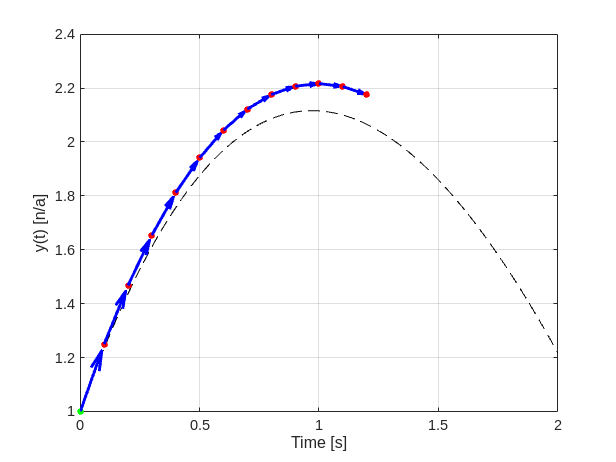

## Separation Principle:  Keep algorithm separate from the problem.

Designing to manage complexity

- **Abstraction:** Design the algorithm to handle general cases rather than specifics, focusing on inputs and outputs that can work across multiple situations.

- **Modularity**: Keep the core logic (like Euler’s method) in a standalone function. This way, the same function can be applied to various ODEs without modifying its internals.

For example, Specific Problem:


$$\dot{y}(t,y) = 3 - 2 \, t - \frac{1}{2} \, y  \\
y(0) = 1
$$


Euler Algorithm (Solver)


$$y_{n+1} = y_n + \dot{y}(t_n, y_n) \, \Delta t   \, \, \, \, \, \, \, n=0,1,2, \ldots$$


As we saw with the `fzero` examples, a good way to separate an algorithm from the specific application is to use a *function handle *to pass the problem to the solver.  Sor for Euler's method this might look like...

**Define the problem as a function**

function dydt = boyce(t, y)
    dydt = 3 - 2*t - 0.5*y;
end

Then we can define a general purpose Euler solver.  We only need to change the function handle to apply to other specific cases.

% Specify the problem as a function handle and point it to our example
rate_func = @boyce;

% Initial conditions
t_euler = [0];
y_euler = [1];
% Time step and span
t_end = 2.0;
dt = 0.1;
% Iteration to implement Euler
while t_euler(end) < t_end
    dydt = rate_func(t_euler(end), y_euler(end));
    t_euler(end+1) = t_euler(end) + dt;
    y_euler(end+1) = y_euler(end) + dydt * dt;
end

Visualize with the exact solution for reference.

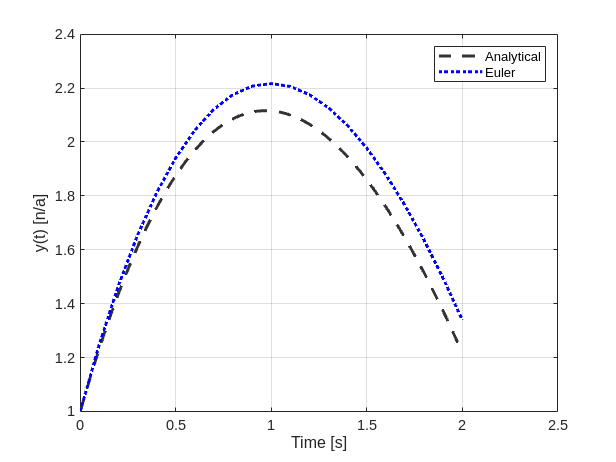

% Visualize
figure(1);
clf;
tt = linspace(0, 2, 100);
y_exact = 14-4*tt-13*exp(-tt/2);
figure;
clf;
plot(tt, y_exact, '--', 'Color', [0.2 0.2 0.2], 'linewidth',2, 'DisplayName', "Analytical")
hold on
plot(t_euler, y_euler,'b:','linewidth', 2, 'DisplayName','Euler')
xlabel("Time [s]")

ylabel("y(t) [n/a]")
grid('on')
legend()

## MATLAB ODE Solvers

MATLAB offers a varitey of solver options ([MATLAB ODE solvers](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)).  While the have different features, they all share an **interface**.  

*An interface is a contract to perform a certain task in exchange for a set of parameters* - Bjarne Stroustrup (C++ creator)

The ODE Solver Interface

`[t,y] = odeXX(odefun,tspan,y0,options)`

Inputs:

- odefun - Function handle specifying the problem we want to solve.  The signature for the funciton must be `dydt = odefun(t,y)`

- tspan - Interval of time (beginning to end) for the solution

- y0 - Initial condition

- options - (optional) Option structure to control the details of the solver's behavior.

Outputs:

- t - Evaluation points as a vector.

- y - Solution values as an array

(There are more optional outputs which we may cover later.)

### Example: ode45

The [ode45](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html) solver is a popular choice for "typical" problems because it balances accuracy (error) with cost (computational time) and gives reliable results for most non-stiff problems.

Restating our example problem.


$$\dot{y}(t,y) = 3 - 2 \, t - \frac{1}{2} \, y  \\
y(0) = 1
$$


Define our inputs to the solver interface.

odefun = @boyce;
tspan = [0, 2.0];
y0 = 1.0;

Then solve and visualize

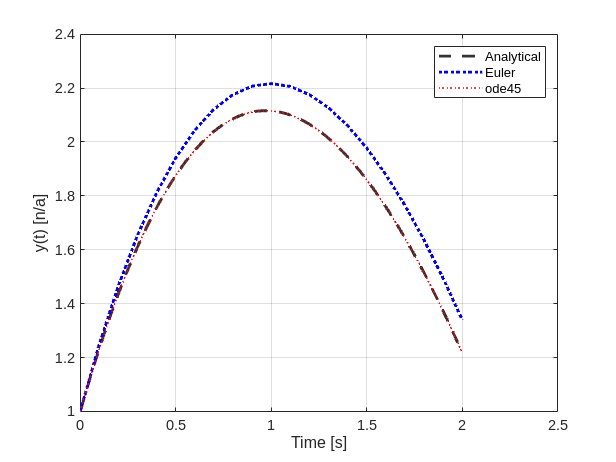

[t_ode, y_ode] = ode45(odefun, tspan, y0);
figure(1)
plot(t_ode,y_ode, 'r:', 'linewidth',1  , 'DisplayName','ode45')

**Visuzalize the ode45 method.**

This is adapted from the PMM section.  The details of the implementation can be skipped - the intent is to provide some introspection on how ode45 operates.  It does use one of the ode solver options which are listed here: [Summary of ODE Options](https://www.mathworks.com/help/matlab/math/summary-of-ode-options.html).

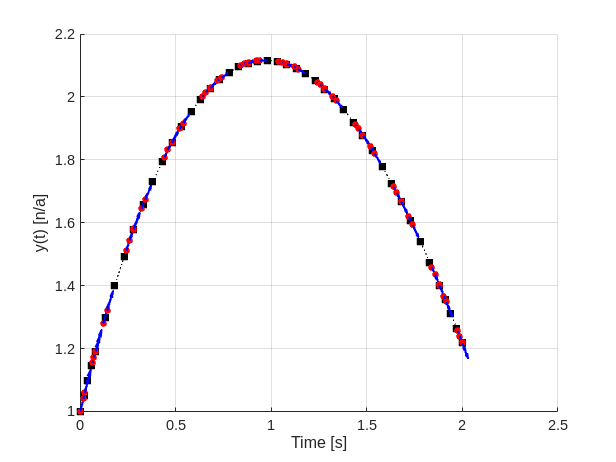

11 successful steps
0 failed attempts
67 function evaluations


function dydt = boyce_viz(t, y)
    dydt = 3 - 2*t - 0.5*y;
    plot(t, y, 'ro','MarkerSize', 4, 'MarkerFaceColor','r');
    quiver(t, y, 1, dydt, 0.03, 'b', 'MaxHeadSize', 1, 'LineWidth',1.5)
end

figure(2);
clf;
hold on
plot(tt, y_exact,'k:')

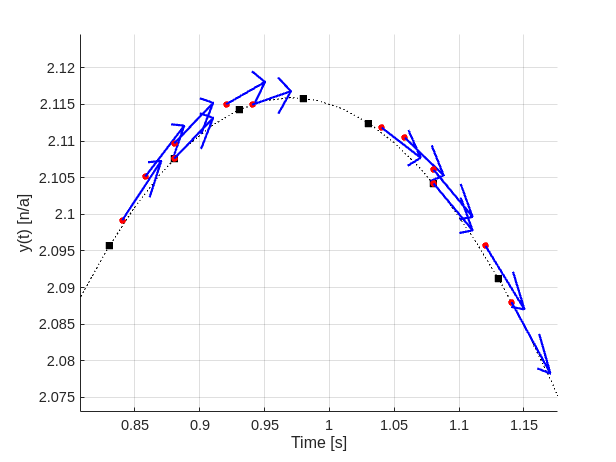

plot(t_ode, y_ode, 'ks', 'MarkerFaceColor','k')
xlabel("Time [s]")
ylabel("y(t) [n/a]")
grid('on')
options = odeset('Refine', 1, 'Stats', 'on');

[t_ode, y_ode] = ode45(@boyce_viz, tspan, y0, options);

- Black squares show the timesteps were ode45 evaluated the ODE.  Note that the timesteps are shorter when the solution is changing more quickly.

- Red circles show where ode45 evaluated the ODE to rate function to improve the estimate

**Zoom**

xlim([0.808 1.176])
ylim([2.0731 2.1246])
